# Lab A Prelab: Introduction to Algebraic Graph Theory

## Part 1: What are Graphs?

Graphs are mathematical objects that describe a collection of points and lines that represent the relationships between the points. Each point is called a **node **(or **vertex**), and each line between two nodes is called an **edge**. Graphs have many interesting theoretical properties that can be interpreted from the perspective of linear algebra, hence the name "algebraic" in the title (however, a systematic course in algebraic graph theory involves concepts developed in *abstract algebra *and are very much out of the scope of our discussion, however, for those of you who are interested, the math department offers introductory graph theory courses that are occasionally taken by engineering students). In this lab and the next, you will learn how to construct some of the matrices used to represent certain properties of a graph, and investigate their properties from the linear algebra concepts you have learned in class so far.

Other than their theoretical properties, graphs are also widely used in engineering applications, and can be used to represent physical networks such as (biological or artificial) neural network, the electricity transmission system, traffic flow, and WiFi networks. Google's first PageRank algorithm heavily uses the concepts from algebraic graph theory as well. 

In this topic, you will be introduced to the subclass of graphs called **directed, simple, **and **connected finite graphs **(quite a mouthful, I know). First, some easy examples:

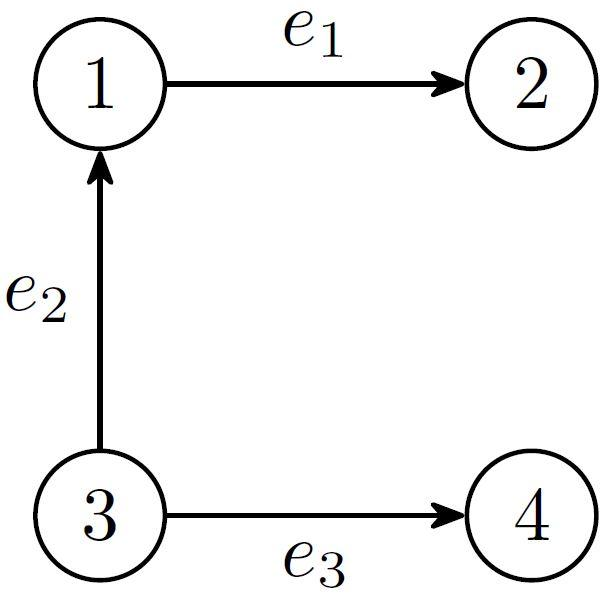                   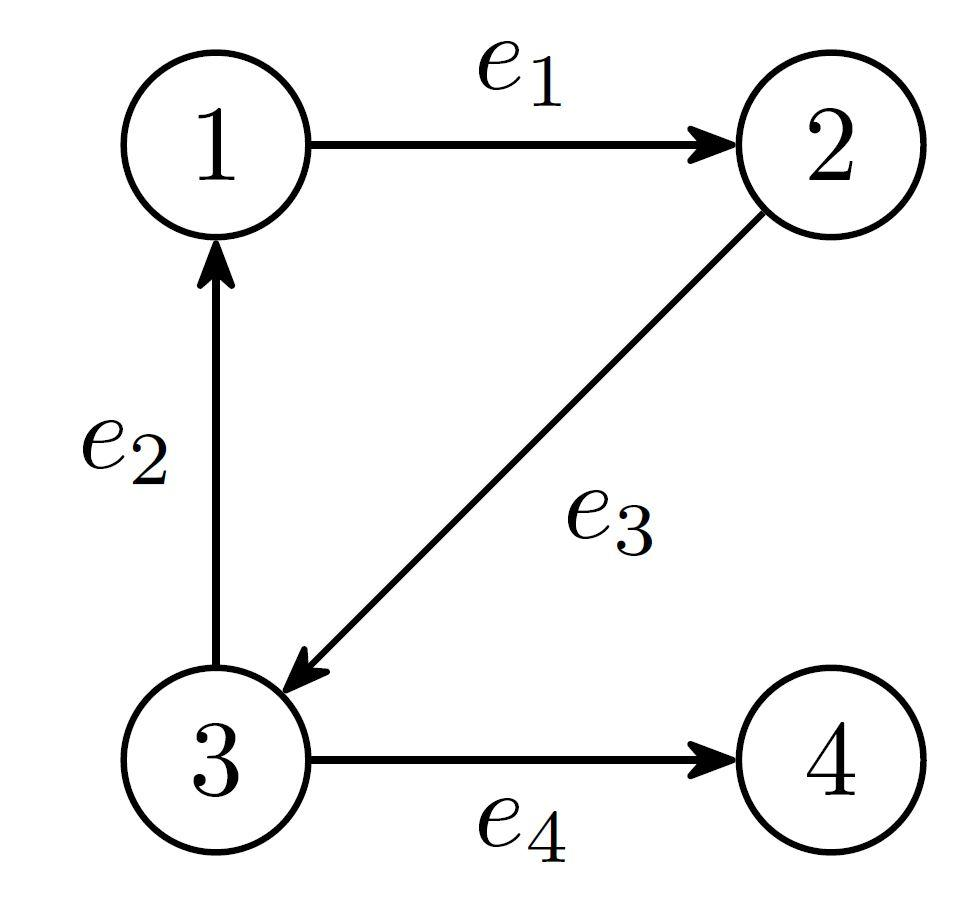

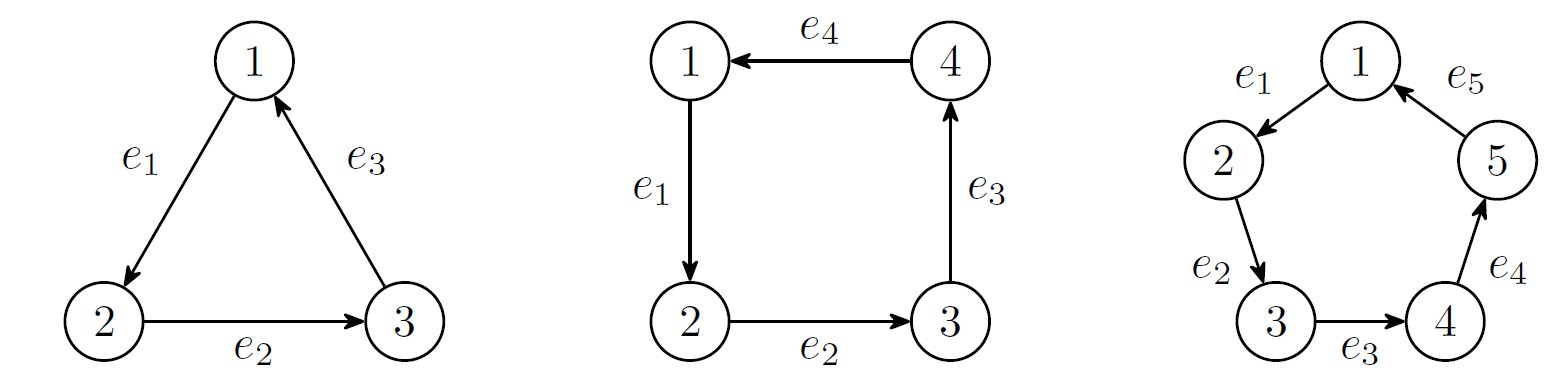

## Nodes

These are denoted by the circles with a number inside in the examples above, for example, **node** $1$ is represented by .  The ***set of nodes*** is denoted by the set $\mathcal{N} = \{1, 2, 3, ..., n\}$. Thus, there are $n$ nodes in a graph. 

## Edges

These are denoted by the arrows with a label in the example above, for example, **edge **$1$ is represented by 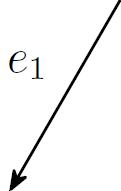. The label $e_1$ here is just for demonstration purposes, and are usually omitted. However, for clarity, we will include them in all ensuing examples. **Note that the labels **$e_i$ **are NOT related to the standard basis vectors you have seen in class.** The ***set of edges*** is denoted by the set $\mathcal{E} = \{e_1, e_2, ..., e_m\}$. In all of our examples above, edge $e_1$ leaves from node $1$ and enters node $2$, so it can be alternatively represented as the tuple $(1,2)$. Note that $e_1$ does not need to go from node $1$ to $2$ in general! If we "reverse" the direction and say the edge $e_1$ leaves from node $2$ and enters node $1$, then it can be represented as $(2,1)$.

Note that each edge also has a direction. For example, if we interpret node $1$ as some city $1$, and node $2$ as some other city $2$, then the direction displayed implies that there is a *one-way* road from city $1$ to city $2$, but not vice-versa. 

Finally, the **simple** term in our graph means that there are no "self-loops," i.e., an edge that connects a node back to itself, and that there is exactly zero or one edge between any two nodes, i.e., if the edge $(i, j)$ is in the set $\mathcal{E}$, then the edge $(j, i)$ is not in the set $\mathcal{E}$, and vice versa. 

## Graph

With the nodes and edges definition above, we can denote the graph by $G$, which is itself a tuple of nodes and edges, i.e., $G = (\mathcal{N}, \mathcal{E})$. 

## Goals of this Topic

The goals are for you to 

- learn how to read the simple, directed and connected finite graphs (which we have done!)

- learn how to construct 4 basic graph-related matrices (or simply, *graph matrices*)

- investigate some simple properties of each graph matrix using the materials you have learned in class so far, and how they are interconnected with each other. 

In the remainder of the prelab, you will learn the two simplest graph matrices out of the total four we will introduce. 

## Part 2: Degree Matrix

First, a simple definition: the **degree **of a node in a graph $G$ is the **number of edges leaving the node + number of edges entering the node**. 

Note that the degree is a **nodal** quantity, which means that edges have no notion of degrees. 

The **Degree Matrix**, denoted by $D$, is a *diagonal matrix *with the degree of nodes $1, 2, ..., n$ on the first, second, ..., $n$-th diagonal element. For example, with the graph below, 

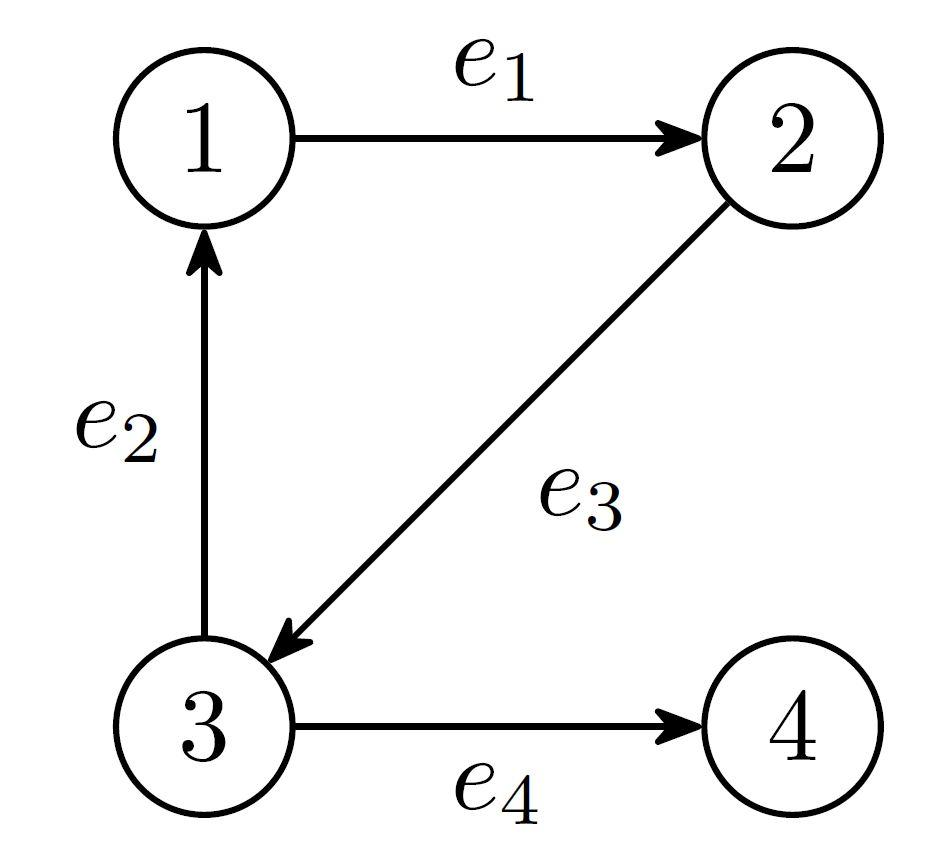

We can conclude that $D = \pmatrix{
2 & 0 & 0 & 0 \cr
0 & 2 & 0 & 0 \cr
0 & 0 & 3 & 0 \cr
0 & 0 & 0 & 1}$ based on the following observations:

- For node $1$, edge $e_1$ leaves from it and edge $e_2$ enters into it, so a total of $2$

- For node $2$, edge $e_3$ leaves from it and edge $e_1$ enters into it, so a total of $2$

- For node $3$, edges $e_2, e_4$ leave from it and edge $e_3$ enters into it, so a total of $3$

- For node $4$, only edge $e_4$ enters into it, so a total of $1$

On Matlab, we can construct the matrix $D$ in two ways: first, we can do it the tedious way, 

D = [2 0 0 0; 0 3 0 0; 0 0 3 0; 0 0 0 1]

D =      2     0     0     0
     0     3     0     0
     0     0     3     0
     0     0     0     1


Or, since $D$ is a diagonal matrix and most of its entries are zeros, we can use the `diag` command with only the diagonal elements as a vector as the input:

D = diag([2;2;3;1])

D =      2     0     0     0
     0     2     0     0
     0     0     3     0
     0     0     0     1


Run these two commands and check that they give the same answer. Does the result change if, instead, we use a *row vector* as the input? Check by running the folloing command:

D = diag([2,2,3,1])

D =      2     0     0     0
     0     2     0     0
     0     0     3     0
     0     0     0     1


## Part 3: Adjacency Matrix

As the name suggests, the **adjacency matrix** $\Delta$ represents the nodes that are adjacent to each other in a graph. Each $(i, j)$-th entry of $D$ is $1$ if the edge $(i, j)$ is in the set $\mathcal{E}$, or if the edge $(j, i)$ is in the set $\mathcal{E}$. (*Strictly speaking, this construction is not precisely the definition of the adjacency matrix of a **directed** graph, but we do not need to worry about that here.*) That is, $\Delta$ is a symmetric matrix, and its diagonal elements are strictly $0$. Again with the previous example (reproduced below)

We can check that $\Delta = \pmatrix{
0 & 1 & 1 & 0 \cr
1 & 0 & 1 & 0 \cr
1 & 1 & 0 & 1 \cr
0 & 0 & 1 & 0
}$ since 

- Edge $e_1 = (1,2)$, so $\Delta_{12} = \Delta_{21} = 1$, 

- Edge $e_2 = (3,1)$, so $\Delta_{31} = \Delta_{13} = 1$, 

- Edge $e_3 = (2,3)$, so $\Delta_{23} = \Delta_{32} = 1$, 

- Edge $e_4 = (3,4)$, so $\Delta_{34} = \Delta_{43} = 1$.

The diagonal entries must all be zeros, since if they were $1$, then an edge must connect a node back to itself, which is not allowed in our context. 

### Exercise

Construct the matrix $\Delta$ (`Delta`) on Matlab and display the result:

% Your code here
Delta = [0 1 1 0; 1 0 1 0; 1 1 0 1; 0 0 1 0]

Delta =      0     1     1     0
     1     0     1     0
     1     1     0     1
     0     0     1     0


You can check that the matrix $\Delta$ is indeed symmetric by running the following command: 

issymmetric(Delta)

ans = logical
   1


The `issymmetric` command tells you whether a matrix is symmetric. It will return either `true `(a "logical 1") or `false `(a "logical 0"). 